clc
clear
close all

# Givens

pi_c = 3;
mdot = 50;
N = 10000;
DF = 0.5;
Tt1 = 288;
Pt1 = 101325;
Cp = 1004.5;

# assumption

Cx = 150;
eta_c = 0.9;

# Choosing values from given table

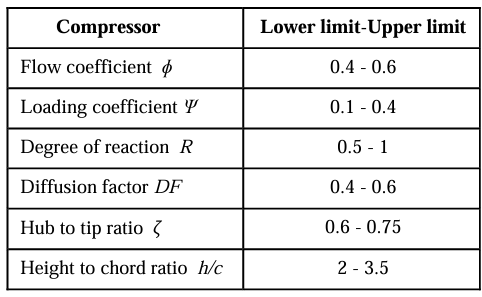

phi = 0.6;
epsi = 0.379285;
R = 0.5;
h_c = 3.5;

# Calculations 

## Compressor total temperature ratio

Taw_c = 1+(pi_c^(0.4/1.4)-1)/eta_c

Taw_c = 1.4097

dela_t_c = (Taw_c-1)*Tt1

dela_t_c = 117.9962

## Velocity triangles

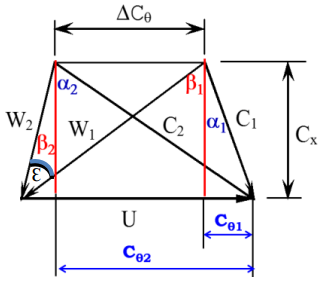

#### Velocity triangle 1

beta1 = atan((R+0.5*epsi)/phi)*180/pi

beta1 = 48.9762

alpha1 = atan((1-R-0.5*epsi)/phi)*180/pi

alpha1 = 27.3508

Ctheta1 =Cx*tan(alpha1*pi/180)

Ctheta1 = 77.5894

Wtheta1 = Cx*tan(beta1*pi/180)

Wtheta1 = 172.4106

W1 = Cx/cos(beta1*pi/180)

W1 = 228.5288

C1 = Cx/cos(alpha1*pi/180)

C1 = 168.8790

#### Velocity triangle 2

beta2 = atan((R-0.5*epsi)/phi)*180/pi

beta2 = 27.3508

alpha2 = atan((1-R+0.5*epsi)/phi)*180/pi

alpha2 = 48.9762

Ctheta2 =Cx*tan(alpha2*pi/180)

Ctheta2 = 172.4106

Wtheta2 = Cx*tan(beta2*pi/180)

Wtheta2 = 77.5894

W2 = Cx/cos(beta2*pi/180)

W2 = 168.8790

C2 = Cx/cos(alpha2*pi/180)

C2 = 228.5288


U = W1*sin(beta1*pi/180)+C1*sin(alpha1*pi/180)       

U = 250

rm = 60*U/2/pi/N                                 %blade mean radius

rm = 0.2387

## Stage Work

W_s = U*(Ctheta2-Ctheta1)*mdot

W_s = 1.1853e+06

## Stage temperature increase

Tt2 = Tt1 + W_s/mdot/1004.5

Tt2 = 311.5991

delta_t_s = Tt2-Tt1

delta_t_s = 23.5991

## number of stages

Z = dela_t_c/delta_t_s

Z = 5.0000

## Total compressor work

W = W_s*Z

W = 5.9264e+06

## calculation of solidity

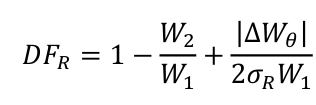                                                       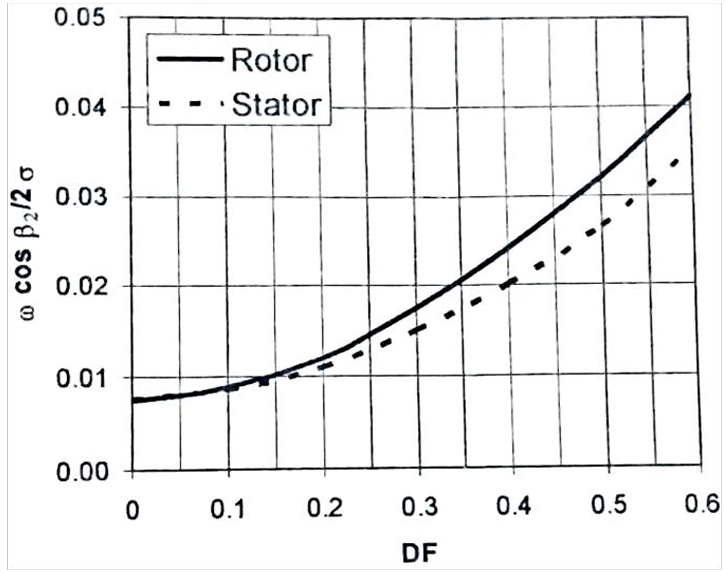

Solidity_r = abs(Wtheta1-Wtheta2)/2/W1/(DF+W2/W1-1)

Solidity_r = 0.8681

Solidity_s = abs(Ctheta1-Ctheta2)/2/C2/(DF+C1/C2-1)

Solidity_s = 0.8681

%from graph
omega_r = 0.0315;
omega_s = 0.0265;

## calculation of temperatures and pressures

### For rotor

T1 = Tt1-C1^2/2/1004.5

T1 = 273.8038

Ttrel1 = T1+W1^2/2/1004.5

Ttrel1 = 299.7996

T2 = Tt2-C2^2/2/1004.5

T2 = 285.6034

Ttrel2 = T2+W2^2/2/1004.5

Ttrel2 = 299.7996

P1 = Pt1*(T1/Tt1)^(1.4/0.4)

P1 = 8.4895e+04

Ptrel1 = P1*(Ttrel1/T1)^(1.4/0.4)

Ptrel1 = 1.1661e+05

Ptrel2 = Ptrel1-omega_r*(Ptrel1-P1)

Ptrel2 = 1.1562e+05

P2 = Ptrel2*(T2/Ttrel2)^(1.4/0.4)

P2 = 9.7561e+04

Pt2  = P2*(Tt2/T2)^(1.4/0.4)

Pt2 = 1.3234e+05

### For stator

Pt3 = Pt2-omega_s*(Pt2-P2)

Pt3 = 1.3142e+05

### Stage adiabatic efficiency

pi_s = Pt3/Pt1

pi_s = 1.2970

Taw_s = Tt2/Tt1

Taw_s = 1.0819

eta_s = (pi_s^(0.4/1.4)-1)/(Taw_s-1)

eta_s = 0.9413

### Geometry

rho1 = P1/287/T1

rho1 = 1.0803

rho2 = P2/287/T2

rho2 = 1.1902

A1 = mdot/rho1/Cx

A1 = 0.3085

A2 = mdot/rho2/Cx

A2 = 0.2801

h = A1/2/pi/rm

h = 0.2057

r_hub = (2*rm-h)/2

r_hub = 0.1359

r_tip = h+r_hub

r_tip = 0.3416

zeta = r_hub/r_tip

zeta = 0.3978

### Calculation of mach number at different stages

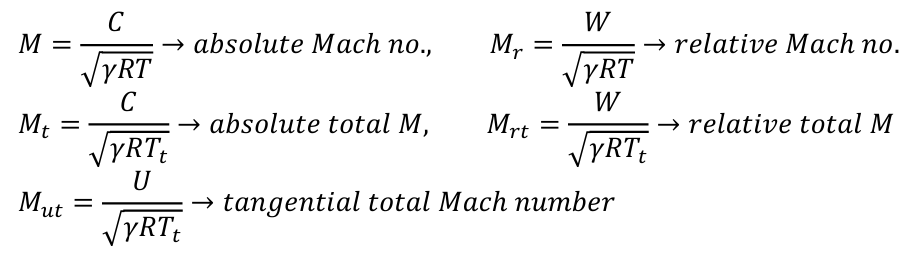

% for state 1
M1 = C1/sqrt(1.4*287*T1)

M1 = 0.5092

Mt1 = C1/sqrt(1.4*287*Tt1)

Mt1 = 0.4964

Mr1 = W1/sqrt(1.4*287*T1)

Mr1 = 0.6890

Mrt1 = W1/sqrt(1.4*287*Tt1)

Mrt1 = 0.6718

Mut1 = U/sqrt(1.4*287*Tt1)

Mut1 = 0.7349

%for state 2
M2 = C2/sqrt(1.4*287*T2)

M2 = 0.6746

Mt2 = C2/sqrt(1.4*287*Tt2)

Mt2 = 0.6459

Mr2 = W2/sqrt(1.4*287*T2)

Mr2 = 0.4985

Mrt2 = W2/sqrt(1.4*287*Tt2)

Mrt2 = 0.4773

Mut2 = U/sqrt(1.4*287*Tt2)

Mut2 = 0.7065

## Blade angles

### using NACA 65-(15)10 airfoil

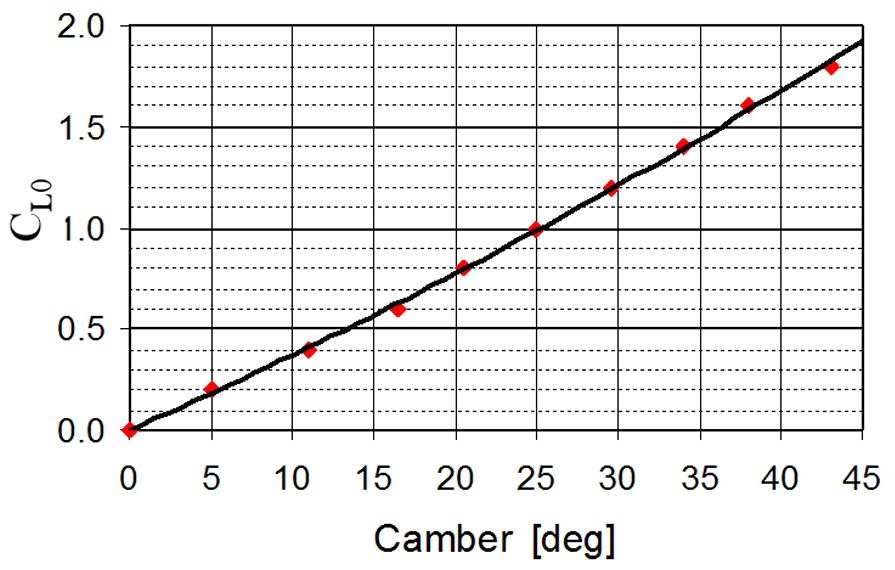

% from graphs
camber_angle = 36

camber_angle = 36

                              

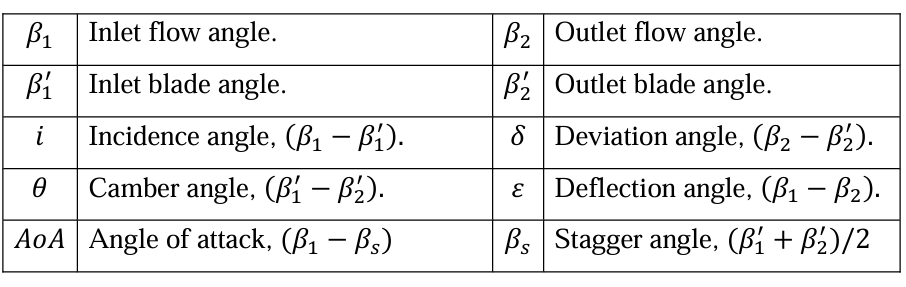

m = 0.23*(2*0.5)^2+alpha2/500

m = 0.3280

deviation_angle = m*camber_angle/Solidity_r^0.5

deviation_angle = 12.6716

blade_angle_2 = beta2-deviation_angle

blade_angle_2 = 14.6793

blade_angle_1 = camber_angle+blade_angle_2

blade_angle_1 = 50.6793

incidence_angle = beta1-blade_angle_1

incidence_angle = -1.7031

deflection_angle = beta1-beta2

deflection_angle = 21.6254

stagger_angle = (blade_angle_1+blade_angle_2)/2

stagger_angle = 32.6793

AoA = beta1-stagger_angle

AoA = 16.2969

## estimating axial compressor length

chord = h/h_c

chord = 0.0588

length = 2*chord*Z+chord

length = 0.6465

## Number of blades

Z_blades = ceil(2*pi*rm*Solidity_r/chord)

Z_blades = 23